# ECE203 Prelab 02

Author: Barry Van Veen, code adapated from Rebecca Willett Lab 0, 2016. Converted to Live Script by Eduardo R. Arvelo, 01/2021

## Section 1: Prepare environment

clear all   % clears all variables from memory
close all   % closes all figures
clc         % clears the command window

## Section 2: Generate a sinusoidal signal

Ts = 0.001;  % sampling interval in seconds
% a semi-colon at the end of a line prevents it from being "printed" to the
% screen

tn = -0.02:Ts:0.08;  
% tn is vector of time samples
% start time -0.02 sec, increment each sample by Ts sec, end time 0.08 sec

A = 5;   % this is the sinusoid amplitude
f0 = 50; % sinusoid frequency in Hz
phi = 0; % sinusoid phase

x = A*cos(2*pi*f0*tn + phi); % vector containing sinusoid

## Section 3: Plot the sinusoid

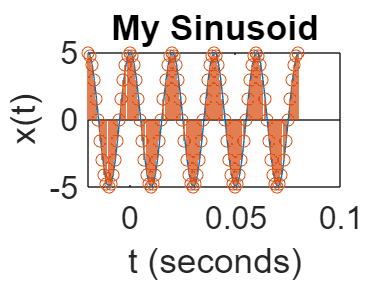

plot(tn,x); % plot sinusoid as continuous curve in the current figure window

hold on     % hold current plot so subsequent commands will add to figure
stem(tn,x); % plot sinusoid as stems
hold off    % release the hold on this figure

xlabel('t (seconds)')   % label x-axis
ylabel('x(t)')          % label y axis
title('My Sinusoid')    % title

set(gca,'fontsize',16); % optional command to make font bigger

## Section 4: Create two-tone signal

The following code generates 3 seconds of a signal consisting of a sum of two sinusoids, one with frequency 440 Hz and the other 720 Hz, using the interval between samples of the sinusoids of 1/8000 seconds. 

T = 3;          % total signal duration
Ts = 1/8000;    % sampling interval
f0a = 440;      % sinusoid a frequency
f0b = 720;      % sinusoid b frequency

tn = 0:Ts:T:

tn =          0    0.0001    0.0003    0.0004    0.0005    0.0006    0.0008    0.0009    0.0010    0.0011    0.0013    0.0014    0.0015    0.0016    0.0018    0.0019    0.0020    0.0021    0.0023    0.0024    0.0025    0.0026    0.0027    0.0029    0.0030    0.0031    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0043    0.0044    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


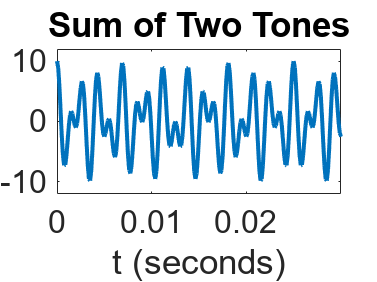

% time samples at which to evaluate the sinusoids
% start at time 0 sec, increment each sample by Ts sec, end at T sec

xa = A*cos(2*pi*f0a*tn); % sinusoid a
xb = A*cos(2*pi*f0b*tn); % sinusoid b

xab = xa+xb; % create new vector x as sum of sinusoids a and b

figure(2);clf
plot(tn,xab,'linewidth',2) % set linewidth of plot to 2 units thick

axis([0,T/100,-A*2.4,A*2.4]); % set limits for plot x- and y-axis
% Here x-axis is restricted to [0,T/100], y-axis to [-2.4*A, 2.4*A]

set(gca,'fontsize',16); % optional command to make font bigger

xlabel('t (seconds)');
title('Sum of Two Tones');


Fs = 1/Ts;      % sampling rate: number of samples in one second
soundsc(xa,Fs)  % plays sinusoid a over speaker/headphones
pause(T+1)      % used to make sure sound buffer empties before next command

% if sound buffer is not empty and another sound is played, the two sounds
% will play on top of each other

soundsc(xb,Fs)  % plays sinusoid b over speaker/headphones
pause(T+1)

soundsc(xab,Fs) % plays two-tone sinusoid over speaker/headphones
pause(T+1)